## This code generates more EEG samples per subject by changing the highpass and lowpass filter ranges

## INITIAL VARIABLES

preprocdata = 'D:\reref_copy\'; % Directory to move weights to
weightedDataPath = 'D:\pruned\'; % Directory with ICA weights
filteredDataPath = 'D:\EEG_Data\'; % Directory containig filtered EEG


## TRANSFER WEIGHTS TO RAW EEG

subjects = (1:29);

for subject = subjects

    % Create new EEG structures
    eeglab;

    % update the GUI to a new set
    EEG = eeg_checkset( EEG );
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);
    eeglab redraw;

    if subject <= 9
        subname = strcat('ERPVR_0',num2str(subject));
    else
        subname = strcat('ERPVR_',num2str(subject));
    end

    % Load set file with ICA weights
    EEG_weights = get_EEG(subject, weightedDataPath);
    
    % reload unfiltered data
    EEG = pop_loadset( [subname '_events_reref.set'], preprocdata );
    EEG.setname = [subname '_unfiltered_RUNICAweights']
    EEG.filename = [subname '_unfiltered_RUNICAweights.set'];
    
    % Transfer unmixing weights
    fprintf('\nTransfering ICA weights from training data to original data...')
    EEG.icasphere   = EEG_weights.icasphere;
    EEG.icaweights  = EEG_weights.icaweights;
    EEG.icachansind = EEG_weights.icachansind;
    EEG = eeg_checkset(EEG); % let EEGLAB re-compute EEG.icaact & EEG.icawinv
    
    % Save as RUNICA file with weights
    EEG = eeg_checkset( EEG );
    EEG = pop_saveset( EEG, 'filename', [subname '_unfiltered_RUNICAweight.set'], 'filepath', preprocdata);
    
    % update the GUI to overwrite the current set to reflect a change that has been made
    EEG = eeg_checkset( EEG );
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
    eeglab redraw;
end

## INTERPOLATE 'NAN' AND 'INF' VALUES IN DATA

subjects = (1:29);

for subject = subjects

    % Create new EEG structures
    eeglab;

    % update the GUI to a new set
    EEG = eeg_checkset( EEG );
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);
    eeglab redraw;

    if subject <= 9
        subname = strcat('ERPVR_0',num2str(subject));
    else
        subname = strcat('ERPVR_',num2str(subject));
    end

    % reload unfiltered data
    EEG = pop_loadset( [subname '_unfiltered_RUNICAweight.set'], preprocdata );

    %loop through each channel
    for channel = (1:20)

        % Get truth values of 'nan' and 'inf' values in the channel
        nan_truth = isinf(EEG.data(channel, :));
        non_nan_truth = ~isinf(EEG.data(channel, :));

        % Get index values with non 'nan' and 'inf' values
        non_nan_indeces = find(non_nan_truth);

        % Interpolate the missing values
        EEG.data(channel, nan_truth) = interp1(non_nan_indeces, EEG.data(channel, non_nan_truth), find(nan_truth), 'nearest');
  
    end

    % Save the changes to the current file
    EEG = pop_saveset(EEG, 'savemode', 'resave');

    % update the GUI to overwrite the current set to reflect a change that has been made
    EEG = eeg_checkset( EEG );
    [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
    eeglab redraw;
end

## BANDPASS FILTER X Hz to Y Hz & ICA ARTIFACT REMOVAL

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 1 to 587471 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 587472 to 848985 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 1 to 587471 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 587472 to 848985 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 1 to 587471 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 587472 to 848985 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_01_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 1 to 587471 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 587472 to 848985 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_02_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_03_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_04_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_05_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_06_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_07_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_08_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_09_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_10_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_11_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_12_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 4 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 1 to 226956 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 226957 to 625388 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 1 to 226956 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 226957 to 625388 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 1 to 226956 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 226957 to 625388 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_13_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 1 to 226956 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 226957 to 625388 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_14_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 1 to 345145 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 345146 to 621863 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 1 to 345145 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 345146 to 621863 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 1 to 345145 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 345146 to 621863 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_15_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 1 to 345145 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 345146 to 621863 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_16_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_17_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_18_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_19_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_20_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_21_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_22_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_23_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_24_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_25_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_26_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_27_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 1 to 286337 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 286338 to 793509 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 1 to 286337 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 286338 to 793509 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 1 to 286337 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 286338 to 793509 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_28_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 1 to 286337 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 286338 to 793509 (in samples), please wait...


Done.  What's next?



Computing projection and removing 3 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 1 to 308097 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 15]' Hz) from segment 308098 to 639363 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 1 to 308097 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 16]' Hz) from segment 308098 to 639363 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 1 to 308097 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 17]' Hz) from segment 308098 to 639363 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Abdulsatar\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ERPLAB" v9.00 (see >> help eegplugin_erplab) - new version 9.10 available
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel) - new version 1.4 available
EEGLAB: adding "bva-io" v1.71 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.7.1 available
EEGLAB: adding "neuroscanio" v1.5 (see >> help eegplugin_neuroscanio) - new version 1.6 available


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Creating a new ALLEEG dataset 1


pop_loadset(): loading file D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.set ...
Reading float file 'D:\reref_copy\ERPVR_29_unfiltered_RUNICAweight.fdt'...
Scaling components to RMS microvolt


Channels to be filtered : [ 1:20]


Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 1 to 308097 (in samples), please wait...

Band-pass filtering input data (fc = [ 5 18]' Hz) from segment 308098 to 639363 (in samples), please wait...


Done.  What's next?



Computing projection and removing 2 components ....


Saving dataset...


Creating a new ALLEEG dataset 1


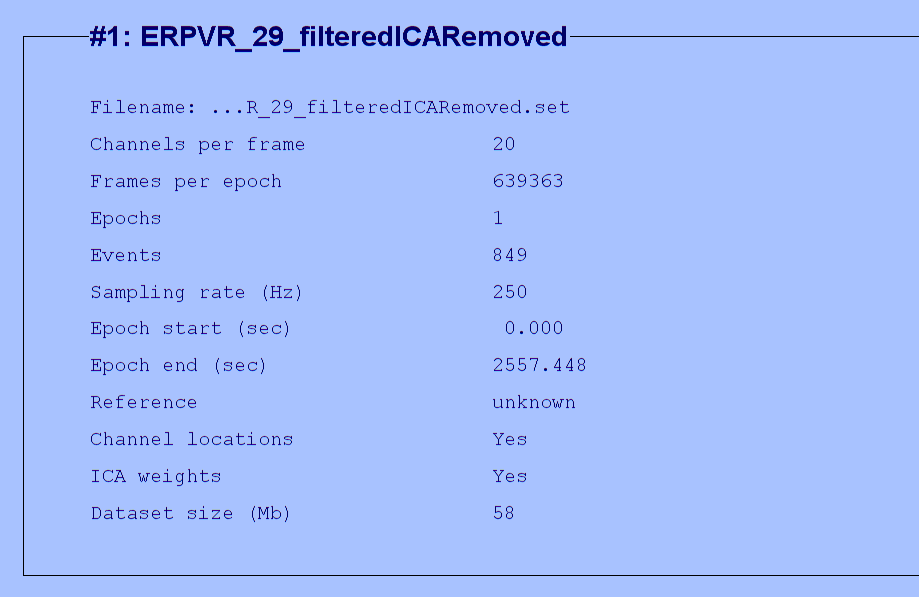

subjects = (1:29);
subjects_components = {[1, 2, 3], [1, 2 ], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2, 3, 4], [1, 2], [1, 2, 3, 4], [1, 3], [1, 2], [1, 2, 3], [1, 2], [1, 2, 3], [1, 2], [1, 4], [1, 2], [1, 2], [1, 2], [1, 2], [2, 3], [1, 2], [1, 2], [1, 2], [1, 2, 4], [1, 2]};
highpass = [5]; % Highpass filter frequency
lowpass = [15,16,17,18]; % Lowpass filter frequency

% subjects = 20;
% highpass = 0.1;
% lowpass = 30;

[X, Y] = meshgrid(highpass, lowpass);
combined = [X(:), Y(:)]; % All the highpass and lowpass combintation

% Create directories of filter combinations
for i = (1:size(combined, 1))
    dir_name = [num2str(combined(i,1)) '_' num2str(combined(i,2))];
    mkdir([filteredDataPath dir_name '\']);
end

for subject = subjects

    if subject <= 9
        subname = strcat('ERPVR_0',num2str(subject));
    else
        subname = strcat('ERPVR_',num2str(subject));
    end

    % Create .set files for all the filter combinations
    for i = (1:size(combined, 1))

        % Create new EEG structures
        eeglab;
    
        % update the GUI to a new set
        EEG = eeg_checkset( EEG );
        [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);
        eeglab redraw;

        % reload unfiltered data
        EEG = pop_loadset( [subname '_unfiltered_RUNICAweight.set'], preprocdata );

        high_band = combined(i,1);
        low_band = combined(i,2);

        subpath = [num2str(high_band) '_' num2str(low_band)]; % save band filtered data in this directory
        
        % bandpass filter the data
        EEG  = pop_basicfilter( EEG,  1:20 , 'Boundary', 'boundary', 'Cutoff', [high_band low_band], 'Design', 'butter', 'Filter', 'bandpass', 'Order',  2 );
        
        % Remove ICA components
        EEG = pop_subcomp( EEG, subjects_components{subject}, 0);

        % Create new file for filtered and ICA removed data
        EEG.setname = [subname '_filteredICARemoved'];
        EEG.filename = [subname '_filteredICARemoved.set'];
        EEG.filepath = [filteredDataPath subpath '\'];
        EEG = eeg_checkset( EEG );
        EEG = pop_saveset( EEG, 'filename', EEG.filename, 'filepath', [filteredDataPath subpath '\']);
        

        % update the GUI to overwrite the current set to reflect a change that has been made
        EEG = eeg_checkset( EEG );
        [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
        eeglab redraw;
    end
    
end

## ICA ARTIFACT REJECTION

% Only used if ICA artifcats were not removed in the previoud stages of the
% process pipline
% Component ID to remove from each subject
subjects_components = {[1, 2, 3], [1, 2 ], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2], [1, 2, 3, 4], [1, 2], [1, 2, 3, 4], [1, 3], [1, 2], [1, 2, 3], [1, 2], [1, 2, 3], [1, 2], [1, 4], [1, 2], [1, 2], [1, 2], [1, 2], [2, 3], [1, 2], [1, 2], [1, 2], [1, 2, 4], [1, 2]};
directory = 'D:\EEG_Data';
bandpass_folders = dir(directory); % Get all the folders with different bandpass ranges

% iterate through each of the bandpass folders
for i = 1:length(bandpass_folders)
   band_folder = bandpass_folders(i); 

   % check if the item is a folder
    if band_folder.isdir && ~strcmp(band_folder.name,'.') && ~strcmp(band_folder.name,'..')
        band_folder_path = fullfile(directory, band_folder.name);
        subject_files = dir(fullfile(band_folder_path, '*.set')); % Get list of all subject set files

        % Iterate through each subject
        for j = 1:length(subject_files)
            subject_file = subject_files(j).name; % Get individual subject file name
            subject_folder = subject_files(j).folder; % Get subject folder name
            
            % Create new EEG structures
            eeglab;
            
            % update the GUI to a new set
            EEG = eeg_checkset( EEG );
            [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);
            eeglab redraw;

            % load subject data
            EEG = pop_loadset( subject_file, subject_folder );
            
            % Remove ICA components
            EEG = pop_subcomp( EEG, subjects_components{j}, 0);
            
            % Save the changes to the current file
            EEG = pop_saveset(EEG, 'savemode', 'resave');
            
            % update the GUI to overwrite the current set to reflect a change that has been made
            EEG = eeg_checkset( EEG );
            [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
            eeglab redraw;
        end
    end
end


## FUNCTIONS

function EEG = get_EEG(partic_id, path_dir)
    if partic_id <= 9
        name = strcat('ERPVR_0',num2str(partic_id),'_RUNICApruned.set');
    else
        name = strcat('ERPVR_',num2str(partic_id),'_RUNICApruned.set');
    end
    
    EEG = pop_loadset('filename',name, 'filepath', path_dir);
end